clear;clc;warning('off','all');close all

P=zpk([],[0 -2 -4],10)

P =
 
       10
  -------------
  s (s+2) (s+4)
 
Continuous-time zero/pole/gain model.





zera=[-1 -10];
bieguny=[-10^13 -10^13];

k=500;
for i=1:length(zera)
    k=k/zera(i);
end
for i=1:length(bieguny)
    k=k*bieguny(i);
end


C=zpk(zera,bieguny,k)

C =
 
  5e27 (s+1) (s+10)
  -----------------
     (s+1e13)^2
 
Continuous-time zero/pole/gain model.



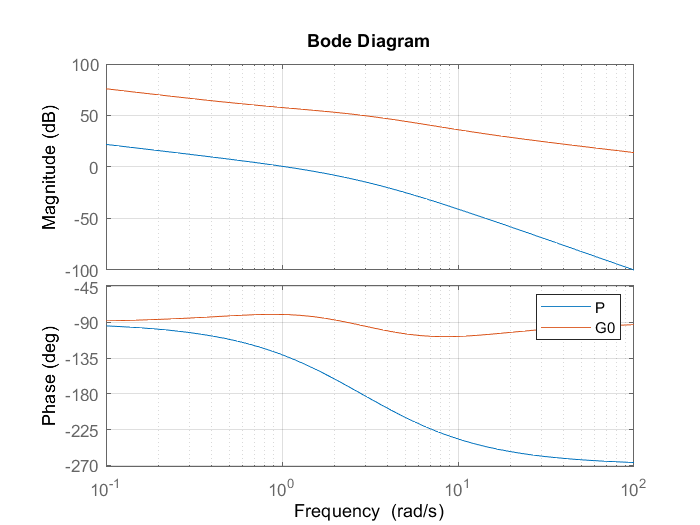

G0=P*C;
bode(P);
hold on;
bode(G0)
hold off;
legend("P","G0")
grid on;

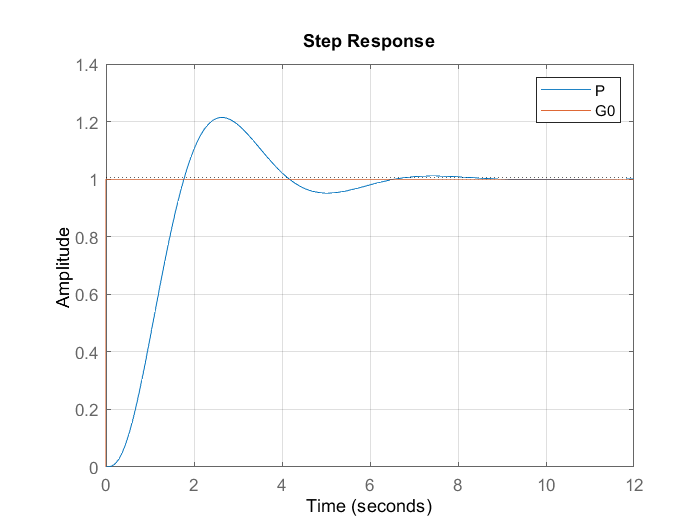

step(feedback(P,1))
hold on;
step(feedback(G0,1))
hold off;
legend("P","G0")
grid on;

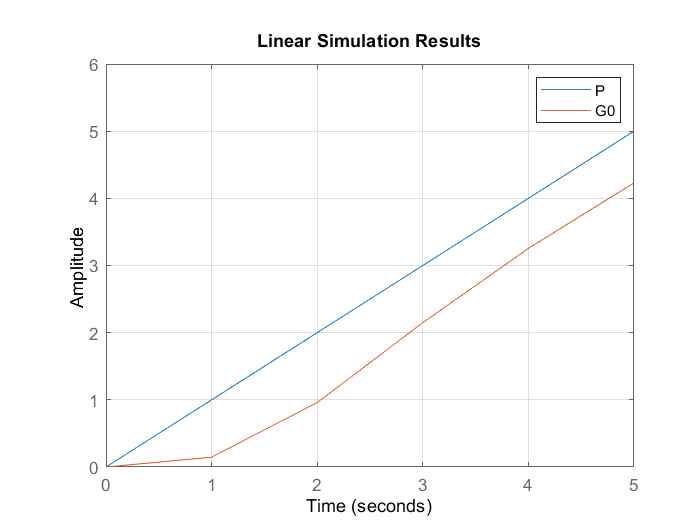

t=(0:5);
u=t;
lsim(feedback(G0,1),u,t)
hold on;
lsim(feedback(P,1),u,t)
grid on;
legend("P","G0")


% lsim(feedback(G0,1),czas,wart)
% czas wartosc 
% zerowe watunki poczatkowe
% control toolbox